## Example from Robust Control note

clc
clear
s = tf('s');
M = [1/(2*s+1), 1, (s-2)/(2*s+4);
    -1, s/(s^2+s+1), 1/(s+1)^2 ;
    (3*s)/(s+5), -1/(4*s+1), 1];

W = logspace(-1,3,1000);
SV = sigma(M, W);
spectral = zeros(1,length(W));
for i=1:length(W)
    spectral(i) = max(abs(eig(evalfr(M,W(i)))));
end

bounds  = mussv(frd(M,W),[1 1; 2 2]);

Points completed: 1000/1000


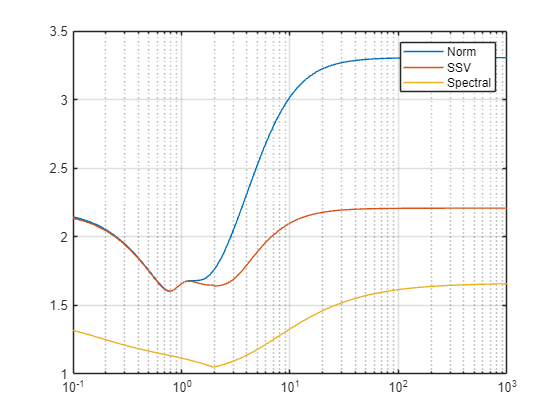


upperBound = bounds(1).ResponseData(:);

semilogx(W,max(SV),W,upperBound,W,spectral)
legend('Norm', 'SSV', 'Spectral')
grid on

## Our system with complex full blocks:


$$\Delta= 
\left[\matrix{\Delta_1 & 0 & 0 & 0 \cr 0 & \Delta_2 & 0 & 0 \cr
0 & 0 & \Delta_3 & 0 \cr 0 & 0 & 0 & \Delta_4}\right], \qquad \Delta_i \in \mathbb{C}, \quad i=1,2,3,4$$


clc
clear

s = tf('s');
M = [(1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0, 0, 0;
      0, (1.312*s^2 - 18.84*s - 5.127)/(s^3 + 2.764*s^2 + 18.97*s + 5.127), 0 , 0;
      0, 0, (1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0 ;
      0, 0, 0, (1.279*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031)];

W = logspace(-1,3,1000);
SV = sigma(M, W);
spectral = zeros(1,length(W));
for i=1:length(W)
    spectral(i) = max(abs(eig(evalfr(M,W(i)))));
end

bounds  = mussv(frd(M,W),[1 1; 1 1; 1 1; 1 1]);

Points completed: 1000/1000


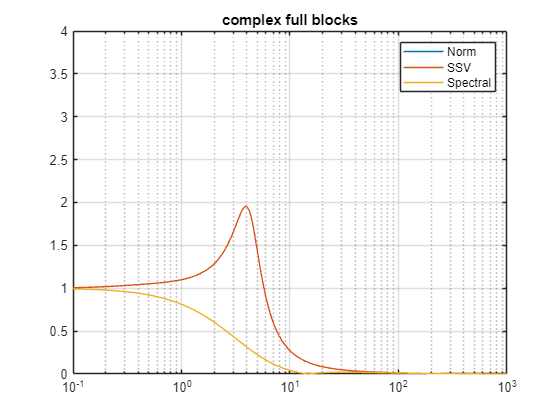


upperBound = bounds(1).ResponseData(:);

semilogx(W,max(SV),W,upperBound,W,spectral)
ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
title('complex full blocks')
grid on

## Our system with one complex full blocks:


$$\Delta \in \mathbb{C}^{4\times 4}$$


clc
clear

s = tf('s');
M = [(1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0, 0, 0;
      0, (1.312*s^2 - 18.84*s - 5.127)/(s^3 + 2.764*s^2 + 18.97*s + 5.127), 0 , 0;
      0, 0, (1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0 ;
      0, 0, 0, (1.279*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031)];

W = logspace(-1,3,1000);
SV = sigma(M, W);
spectral = zeros(1,length(W));
for i=1:length(W)
    spectral(i) = max(abs(eig(evalfr(M,W(i)))));
end

bounds  = mussv(frd(M,W),[4,4]);

Points completed: 1000/1000


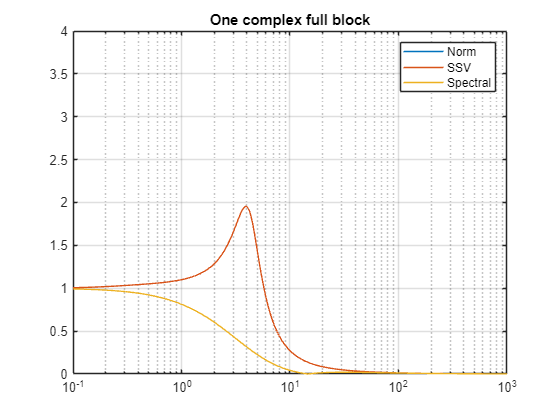


upperBound = bounds(1).ResponseData(:);

semilogx(W,max(SV),W,upperBound,W,spectral)
ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
title('One complex full block')
grid on

## Our system with complex full blocks:


$$\Delta= 
\left[\matrix{\delta_1 & 0 & 0 & 0 \cr 0 & \delta_2 & 0 & 0 \cr
0 & 0 & \delta_3 & 0 \cr 0 & 0 & 0 & \delta_4}\right], \qquad \delta_i \in \mathbb{C}, \quad i=1,2,3,4$$


clc
clear

s = tf('s');
M = [(1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0, 0, 0;
      0, (1.312*s^2 - 18.84*s - 5.127)/(s^3 + 2.764*s^2 + 18.97*s + 5.127), 0 , 0;
      0, 0, (1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0 ;
      0, 0, 0, (1.279*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031)];

W = logspace(-1,3,1000);
SV = sigma(M, W);
spectral = zeros(1,length(W));
for i=1:length(W)
    spectral(i) = max(abs(eig(evalfr(M,W(i)))));
end

bounds  = mussv(frd(M,W),[4,0]);

Points completed: 1000/1000


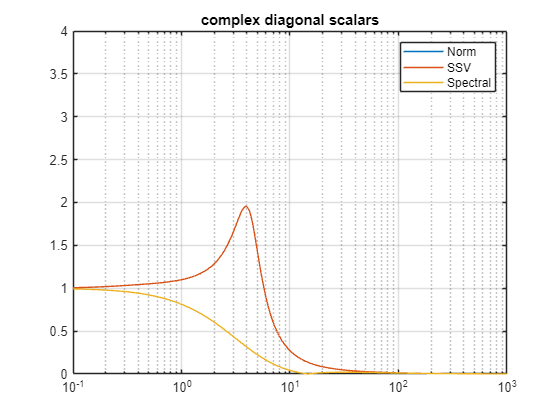


upperBound = bounds(1).ResponseData(:);

semilogx(W,max(SV),W,upperBound,W,spectral)
ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
title('complex diagonal scalars')
grid on

## Our system with real diagonal pertubations:


$$\Delta= 
\left[\matrix{\delta_1 & 0 & 0 & 0 \cr 0 & \delta_2 & 0 & 0 \cr
0 & 0 & \delta_3 & 0 \cr 0 & 0 & 0 & \delta_4}\right], \qquad \delta_i \in \mathbb{R}, \quad i=1,2,3,4$$


clc
clear

s = tf('s');
M = [(1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0, 0, 0;
      0, (1.312*s^2 - 18.84*s - 5.127)/(s^3 + 2.764*s^2 + 18.97*s + 5.127), 0 , 0;
      0, 0, (1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0 ;
      0, 0, 0, (1.279*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031)];

W = logspace(-1,3,1000);
SV = sigma(M, W);
spectral = zeros(1,length(W));
for i=1:length(W)
    spectral(i) = max(abs(eig(evalfr(M,W(i)))));
end

bounds  = mussv(frd(M,W),[-4,0]);

Points completed: 1000/1000


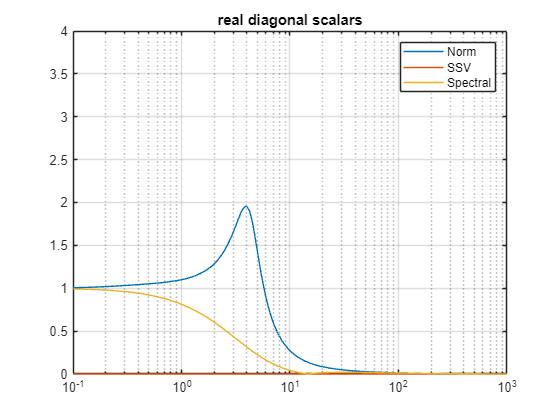


upperBound = bounds(1).ResponseData(:);

semilogx(W,max(SV),W,upperBound,W,spectral)
ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
title('real diagonal scalars')
grid on